# What should the basis functions be for fitting the raw tongue/lip signals?

Some fluorophores are present at different tissue layers.  The superficial layers (epithelial) contain FAD, NADH, and keratin in certain locations.  These are not going to be impacted by blood absorptions.  The blood is below the epithelial layer.

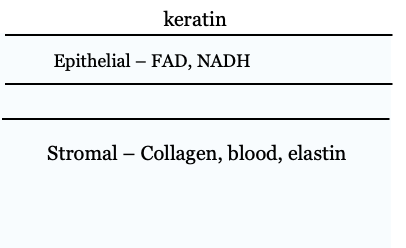

We have data about the excitations of each of these fluorophores.  These are in the isetfluorescence repository.  We are going to read them in and we are also going to read in some examples of raw data taken from our subjects' tongues and lips.  This script will explore how we might create basis functions to predict the raw data as weighted sums of the fluorophore excitations, but combining them as if some of the fluorophores are passing through blood.

The reason we think blood is necessary is because the raw data - directory spectral photometry measures from the tongue and lip - show some signs of the dips that are well known to be part of the blood absorbance (transmittance) measured in different contexts.

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Programming notes

Repositories: isetcam, isetfluorescence and oe_tongue_lip

## Read in the oxy data

For different purposes we might choose different wavebands.  The raw data are pretty much good from 500-670 or so.  The longer wavelengths are mainly porphyrin fluorescence (bacteria on the tongue).

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated.  So 3/4 of the blood is oxygenated.  We might add in deoxy_ in the future.

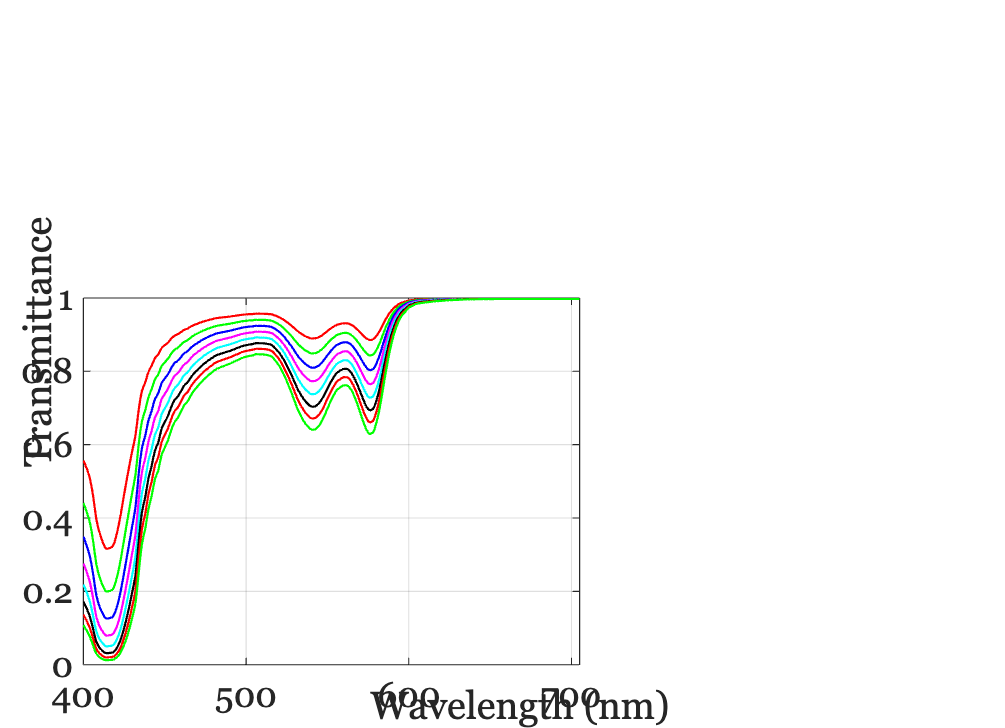

wave = 400:705;
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);

ieNewGraphWin;
for od = (0.5:0.2:2)
    oxyblood.opticalDensity = od;
    plot(wave,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');

Notice that the blood has the two characteristic dips at 540 nm and 580nm.  We see little bumps like that in the raw data.

## Reading the fluorophore emissions

We are going to make all the data fluorophore files.  But for now we have some strays that we read in.  More commenting to come.  Here is a list of the fluorophores.

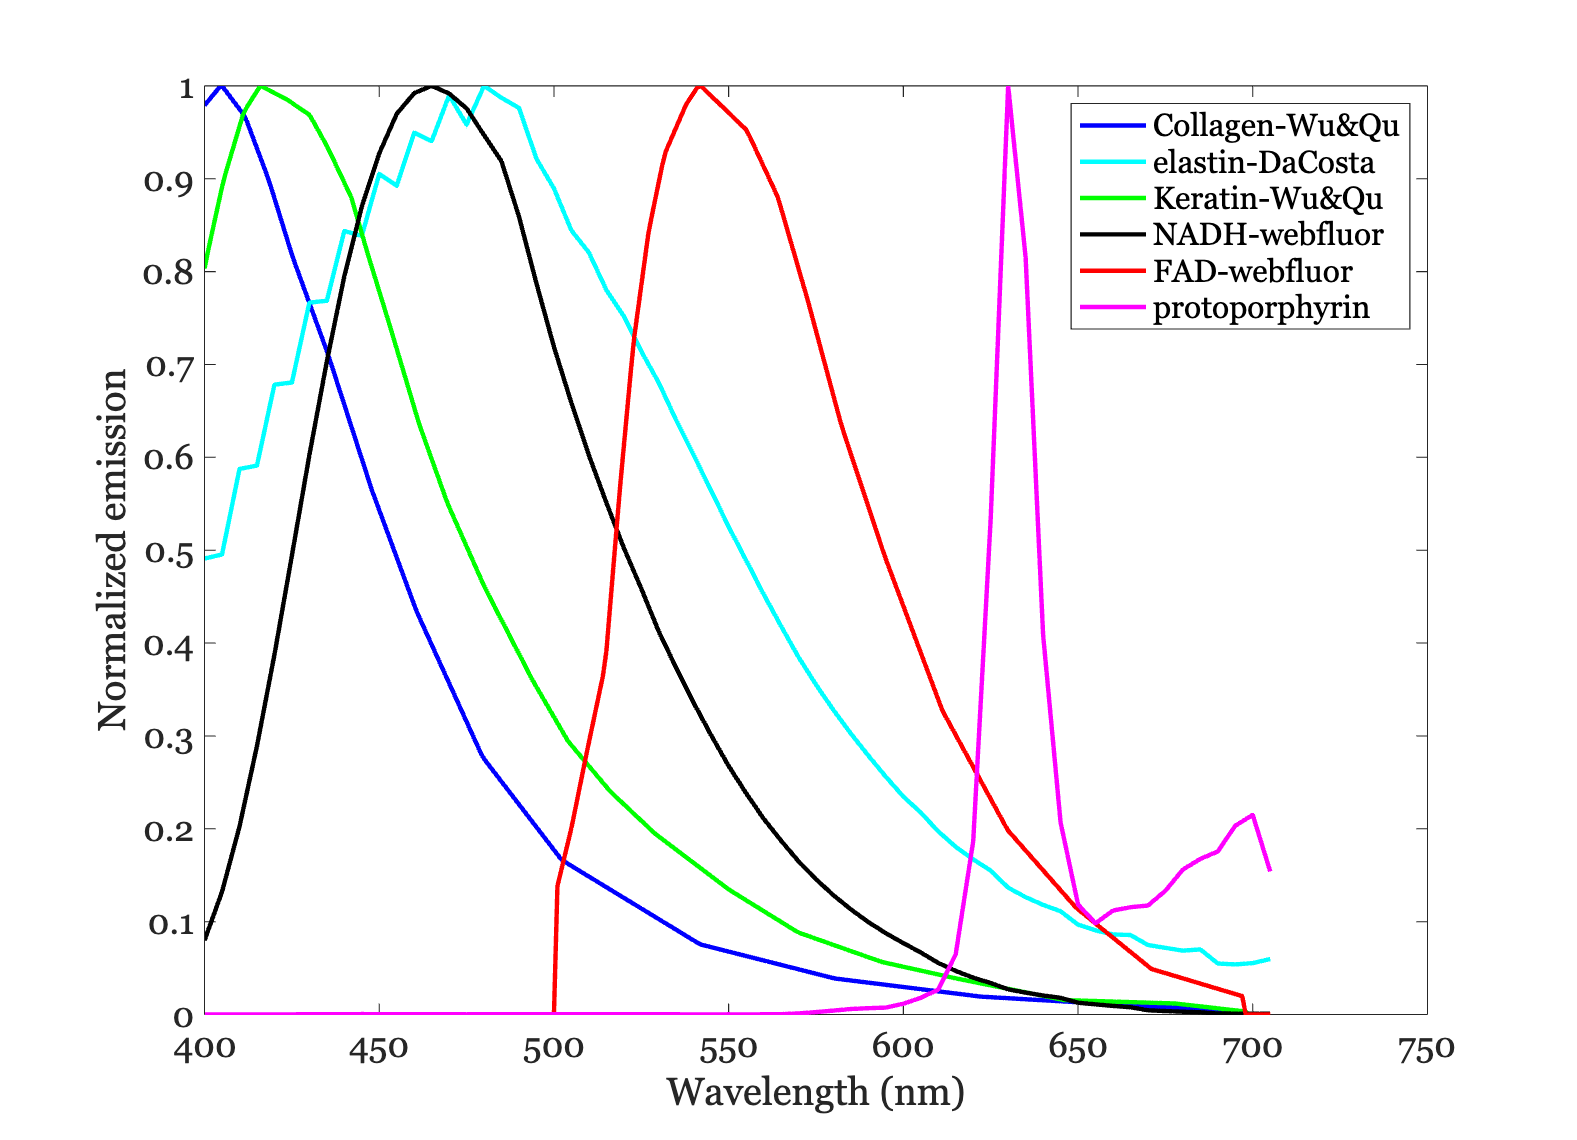

ieNewGraphWin;

collagen = ieReadSpectra('Collagen_Wu&Qu_emissions',wave); 
plot(wave, collagen/max(collagen(:)),'b','LineWidth',2); hold on;

elastin = fiReadFluorophore('elastin_webfluor.mat','wave',wave);
plot(wave, elastin.emission/max(elastin.emission),'c','LineWidth',2);

keratin= ieReadSpectra('Keratin_Wu&Qu_emissions.mat',wave); % use this one
plot(wave, keratin/max(keratin(:)),'g','LineWidth',2);

NADH = fiReadFluorophore('NADH_webfluor.mat','wave',wave); 
plot(wave, NADH.emission/max(NADH.emission(:)),'k','LineWidth',2);hold on; % use this one

FAD = ieReadSpectra('FAD_handbook.mat',wave);
plot(wave,FAD/max(FAD),'r','LineWidth',2);

porphyrins = fiReadFluorophore('protoporphyrin.mat','wave',wave);
plot(wave, porphyrins.emission/max(porphyrins.emission(:)),'m','LineWidth',2); 

legend('Collagen-Wu&Qu','elastin-DaCosta','Keratin-Wu&Qu','NADH-webfluor','FAD-webfluor','protoporphyrin');
set(gca,'fontsize',16);
xlabel('Wavelength (nm)'); ylabel('Normalized emission')

## Read a couple of raw data sets

We chose Z's data because he has little porphyrin. 

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

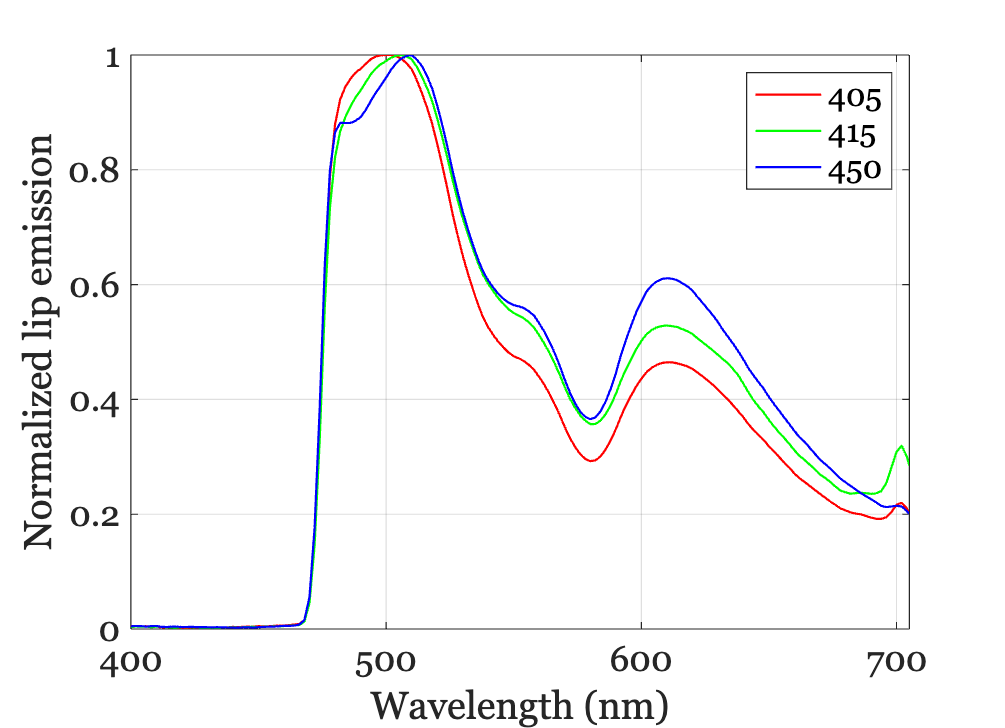

dataDir = fullfile(oeTongueLipRootPath,'data','RawTongueLip');

lipFiles = {'spd-2024-03-14-Z-405nm_lip_980mA.mat';...
    'spd-2024-03-14-Z-415nm_lip_910mA.mat'; ...
    'spd-2024-03-14-Z-450nm_lip_870mA.mat'};

ieNewGraphWin;
for ii=1:numel(lipFiles)
    data = ieReadSpectra(fullfile(dataDir,lipFiles{ii}),wave); 
    plot(wave,data/max(data(:))); hold on;
end
legend({'405','415','450'});
xlabel('Wavelength (nm)'); ylabel('Normalized lip emission'); grid on;

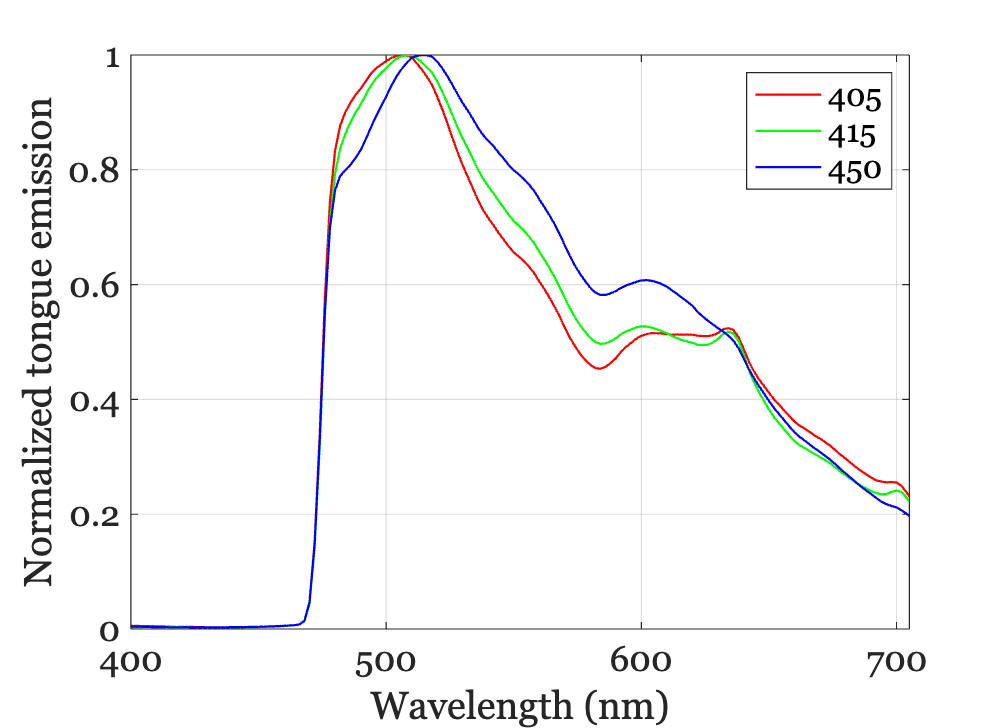

ieNewGraphWin;
tongueFiles = {'spd-2024-03-14-Z-405nm_tongue_980mA.mat'; ...
    'spd-2024-03-14-Z-415nm_Tongue_910mA.mat';
    'spd-2024-03-14-Z-450nm_tongue_870mA.mat'};
for ii=1:numel(tongueFiles)
    data = ieReadSpectra(fullfile(dataDir,tongueFiles{ii}),wave); 
    plot(wave,data/max(data(:))); hold on;
end
legend({'405','415','450'});
xlabel('Wavelength (nm)'); ylabel('Normalized tongue emission')
grid on;

## Select and combine the fluorophores for a basis

First, let's make a large number of basis functions from the fluorophores and the fluorophores modified by blood.  Let's make sure that we can get very close to the raw data when they are overfit this way.

We will make a list of all the fluorophore file names in a cell array.

fluorophoreVariables = {'',...};

% Make a big matrix 
for ff = 1:numel(fluorophores)
    fBasis = [fBasis,fluorophores{ff}];
end

% Modify some with blood and add those in too


Check that the huge one will nicely predict all three of the data samples

Find a solution subject to (a) L1 norm, (b) L2 regularized for smoothness.  Deal with non-negativity as well.